## Project 1 add and estimate noise

### Step 1 加载并绘制原始mri图像

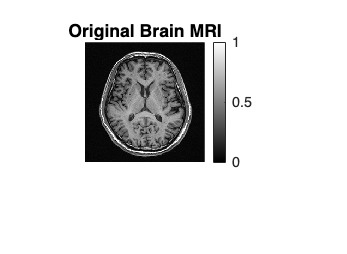

data = load('../data/Lab4_2025_MRI.mat');
variableNames = fieldnames(data);
mriData = data.(variableNames{1}); 
mriData = mat2gray(mriData);

figure;
imshow(mriData, []);
colormap gray;
colorbar;
title('Original Brain MRI');

### Step 2 生成高斯噪声

– Develop a program to add Gaussian noise to an image. Specify the noise mean and variance.

#### Step 2.1 MRI 图像

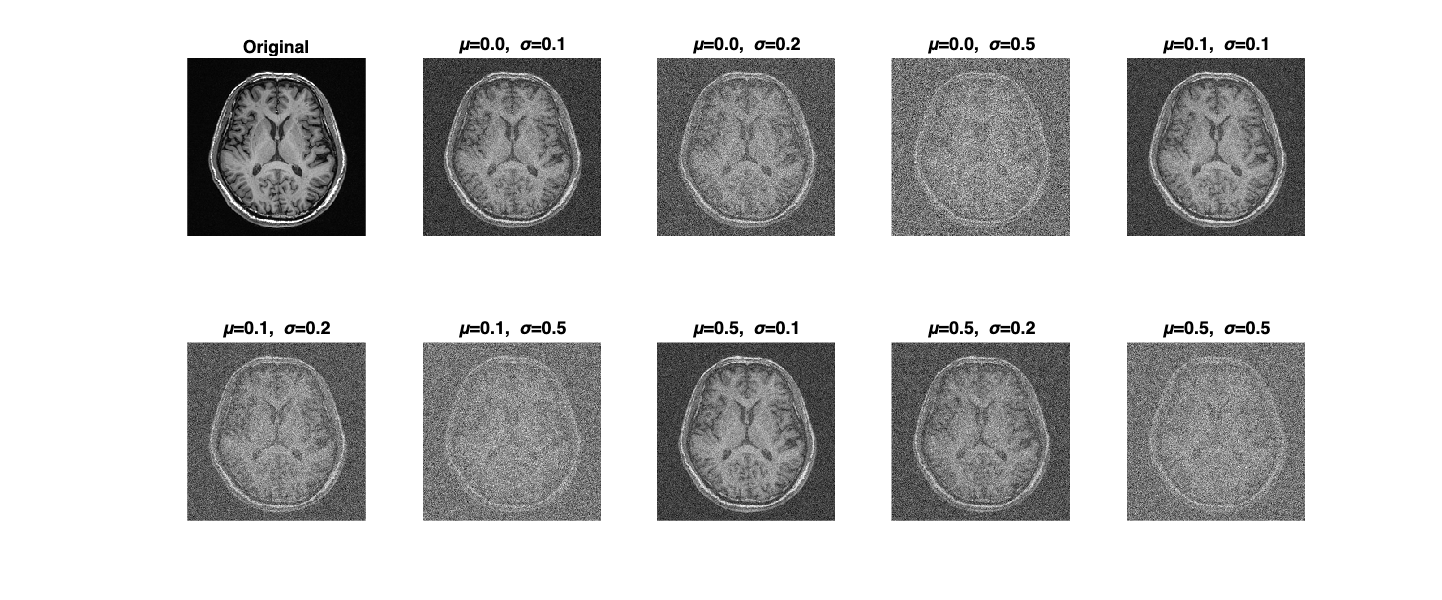

means = [0, 0.1, 0.5];
stds = [0.1, 0.2, 0.5];

figure('Position', [100, 100, 1200, 500]);
subplot(2,5,1);
imshow(mriData, []);
title('Original');

noisyImages = cell(3,3);

im_num = 2;
for i = 1:3
    for j = 1:3
        % 生成高斯噪声
        noise = means(i) + stds(j) * randn(size(mriData));
        noisy = mriData + noise;
        % 限制范围 [0,1]
        % noisy = min(max(noisy, 0), 1);
        noisyImages{i,j} = noisy;

        subplot(2,5,im_num);
        imshow(noisy, []);
        title(sprintf('\\mu=%.1f, \\sigma=%.1f', means(i), stds(j)));
        im_num = im_num + 1;
    end
end

#### Step 2.2 直方图

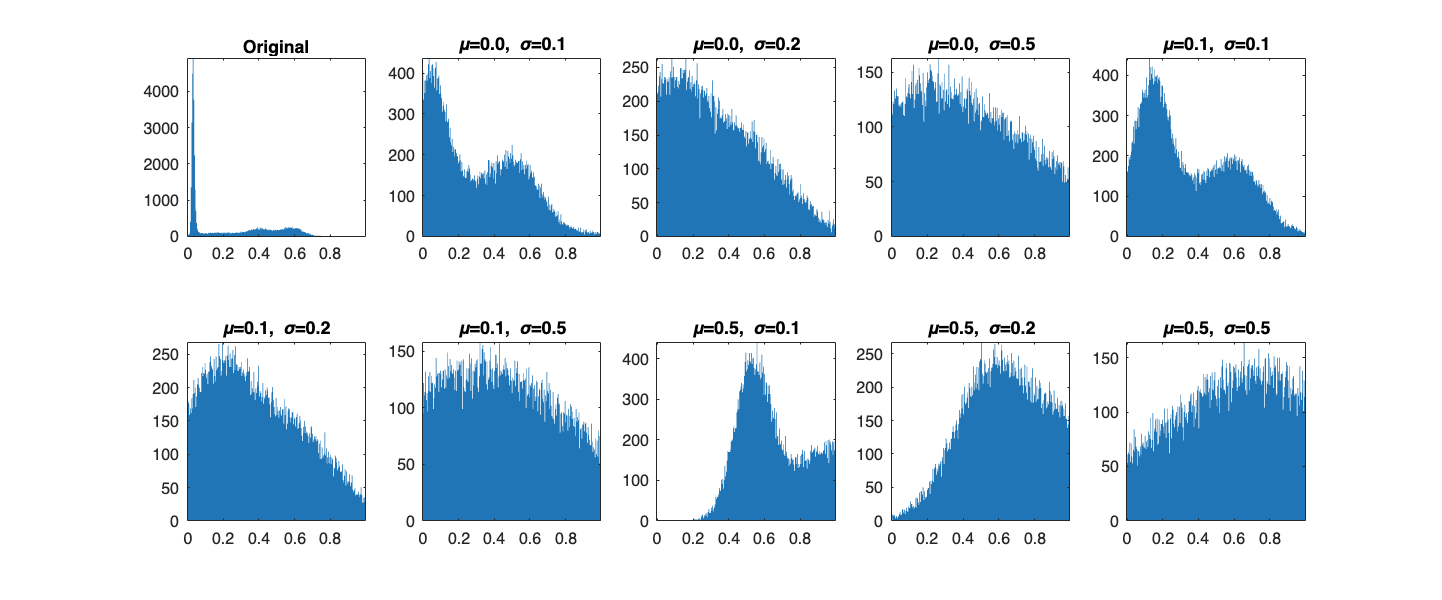

figure('Position', [100, 100, 1200, 500]);
nbins = 256;
edges = linspace(0, 1, nbins+1);

% 原图直方图
subplot(2,5,1);
pixels = mriData(:);
counts = histcounts(pixels, edges);
lightBlue = [0.12, 0.46, 0.71];
bar(edges(1:end-1), counts, 'FaceColor',lightBlue, 'BarWidth', 1);
axis tight;
axis square;
title('Original');

% 加噪图直方图（标题和图像一一对应）
plot_num = 2;
for i = 1:3
    for j = 1:3
        subplot(2,5,plot_num);
        pixels = noisyImages{i,j}(:);
        counts = histcounts(pixels, edges);
        bar(edges(1:end-1), counts,'FaceColor',lightBlue, 'BarWidth', 1);
        axis tight;
        axis square;
        title(sprintf('\\mu=%.1f, \\sigma=%.1f', means(i), stds(j)));
        plot_num = plot_num + 1;
    end
end

#### Step 2.3 估计噪声

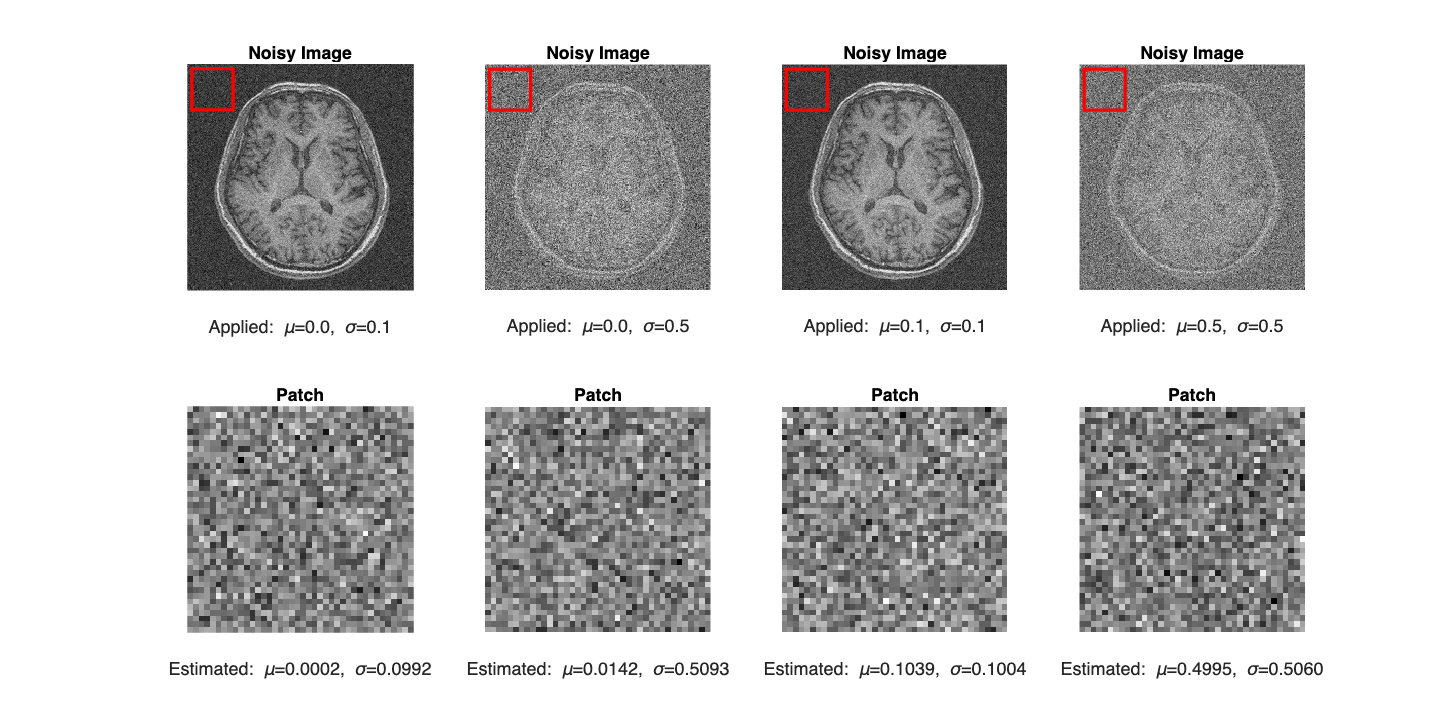

figure('Position', [100, 100, 1200, 600]); 
patch_size = 40; 
selected_combinations = [1 1; 1 3; 2 1; 3 3]; % 选择四组不同噪声的图

% 显示挑选的加噪图
for k = 1:4
    i = selected_combinations(k, 1);
    j = selected_combinations(k, 2);
    selected_noisy_image = noisyImages{i,j};
    start_row = 5;
    start_col = 5;
    patch = selected_noisy_image(start_row:start_row+patch_size-1, start_col:start_col+patch_size-1);
    patch_noise = patch - mriData(start_row:start_row+patch_size-1, start_col:start_col+patch_size-1);
    estimated_mean = mean(patch_noise(:));
    estimated_std = std(patch_noise(:));

    subplot(2, 4, k);
    imshow(selected_noisy_image, []);
    colormap gray;
    title('Noisy Image');
    rectangle('Position', [start_row, start_col, patch_size, patch_size], 'EdgeColor', 'r', 'LineWidth', 2);
    xlabel(sprintf('Applied: \\mu=%.1f, \\sigma=%.1f', means(i), stds(j)));
end

% 显示截取的patch
for k = 1:4
    i = selected_combinations(k, 1);
    j = selected_combinations(k, 2);
    selected_noisy_image = noisyImages{i,j};
    patch = selected_noisy_image(start_row:start_row+patch_size-1, start_col:start_col+patch_size-1);
    patch_noise = patch - mriData(start_row:start_row+patch_size-1, start_col:start_col+patch_size-1);
    estimated_mean = mean(patch_noise(:));
    estimated_std = std(patch_noise(:));

    subplot(2, 4, k + 4);
    imshow(patch, []);
    colormap gray;
    title('Patch');
    xlabel(sprintf('Estimated: \\mu=%.4f, \\sigma=%.4f', estimated_mean, estimated_std));
end    

### Step 3 `添加椒盐噪声`

– Add pepper and salt noise to the image with different parameters

#### Step 3.1 MRI 图像

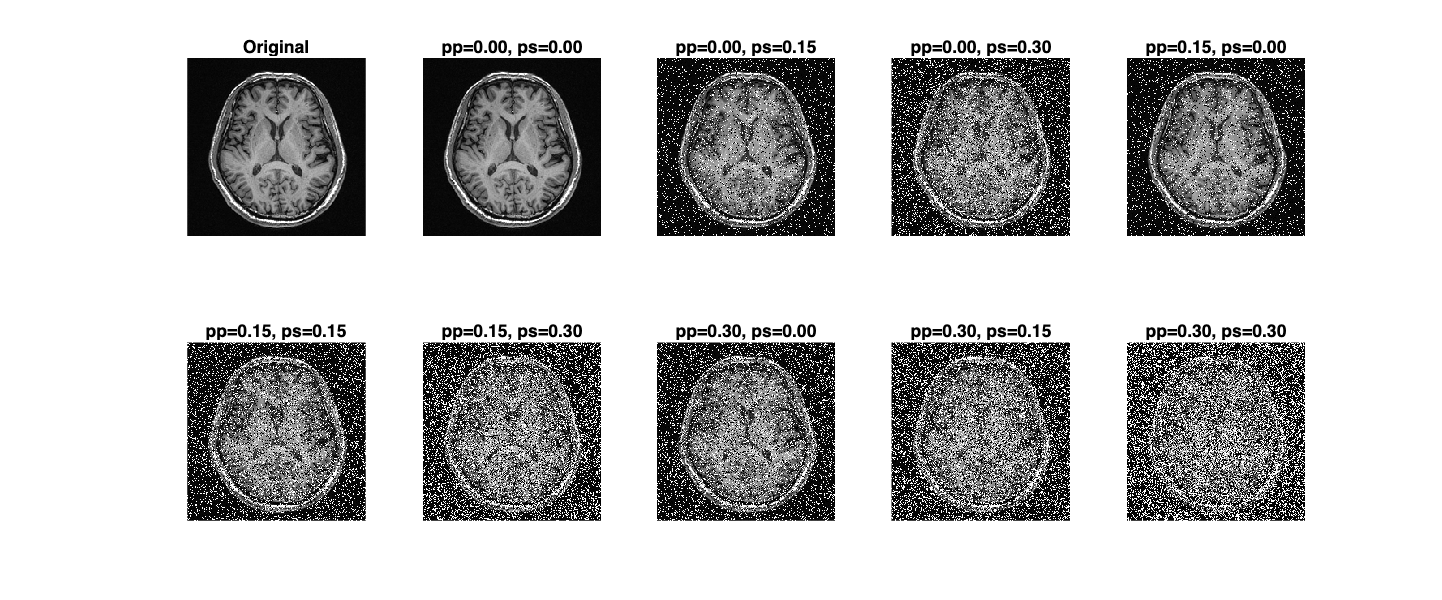

pps = [0, 0.15, 0.3];
pss = [0, 0.15, 0.3];

figure('Position', [100, 100, 1200, 500]);
subplot(2,5,1);
imshow(mriData, []);
title('Original');

noisyImages_salt_pepper = cell(3,3);

im_num = 2;
for i = 1:3
    for j = 1:3
        % 生成椒盐噪声
        noisy = imnoise(mriData, 'salt & pepper', pps(i) + pss(j));
        noisyImages_salt_pepper{i,j} = noisy;

        subplot(2,5,im_num);
        imshow(noisy, []);
        title(sprintf('pp=%.2f, ps=%.2f', pps(i), pss(j)));
        im_num = im_num + 1;
    end
end

#### Step 3.2 估计噪声

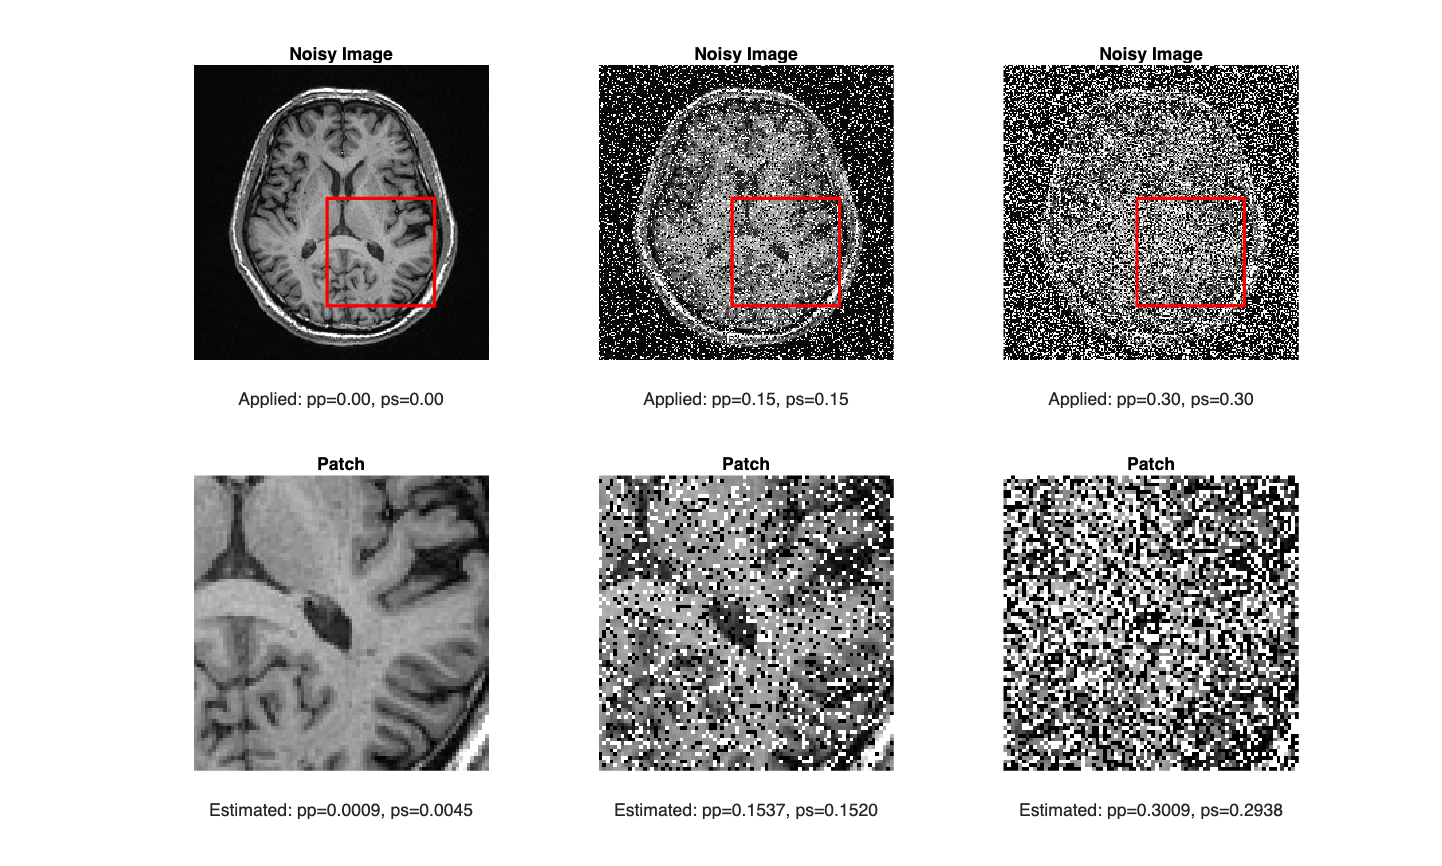

figure('Position', [100, 100, 1000, 600]);
patch_size = 80; % 定义patch大小
selected_combinations_salt_pepper = [1 1; 2 2; 3 3]; % 选择四组不同噪声的图

% 显示挑选的加噪图
for k = 1:3
    i = selected_combinations_salt_pepper(k, 1);
    j = selected_combinations_salt_pepper(k, 2);
    selected_noisy_image = noisyImages_salt_pepper{i,j};
    start_row = 100;
    start_col = 100;
    patch = selected_noisy_image(start_row:start_row+patch_size-1, start_col:start_col+patch_size-1);
    patch_noise = patch - mriData(start_row:start_row+patch_size-1, start_col:start_col+patch_size-1);
    % 椒盐噪声估计均值和标准差的方式与高斯噪声不同，这里简单计算非零值的比例来近似估计
    salt_proportion = sum(patch(:) == 1, 'all') / numel(patch);
    pepper_proportion = sum(patch(:) == 0, 'all') / numel(patch);

    subplot(2, 3, k);
    imshow(selected_noisy_image, []);
    colormap gray;
    title('Noisy Image');
    rectangle('Position', [100, 100, patch_size, patch_size], 'EdgeColor', 'r', 'LineWidth', 2);
    xlabel(sprintf('Applied: pp=%.2f, ps=%.2f', pps(i), pss(j)));
end

% 显示截取的patch
for k = 1:3
    i = selected_combinations_salt_pepper(k, 1);
    j = selected_combinations_salt_pepper(k, 2);
    selected_noisy_image = noisyImages_salt_pepper{i,j};
    patch = selected_noisy_image(start_row:start_row+patch_size-1, start_col:start_col+patch_size-1);
    patch_noise = patch - mriData(start_row:start_row+patch_size-1, start_col:start_col+patch_size-1);
    % 椒盐噪声估计均值和标准差的方式与高斯噪声不同，这里简单计算非零值的比例来近似估计
    salt_proportion = sum(patch(:) == 1, 'all') / numel(patch);
    pepper_proportion = sum(patch(:) == 0, 'all') / numel(patch);

    subplot(2, 3, k + 3);
    imshow(patch, []);
    colormap gray;
    title('Patch');
    xlabel(sprintf('Estimated: pp=%.4f, ps=%.4f', pepper_proportion, salt_proportion));
end